In the design of all-terrain vehicles, it is necessary to consider the failure of the vehicle when attempting to negotiate two types of obstabcles. One type of failure is called *hang-up failure *and occurs when the vehicle attempts to cross an obstacle that causese the bottom of the vehicle to touch the ground. Teh other type of failure is called *nose-in failure* and occurs when the vehicle descends into a ditch and its nose touches the ground.

The accompany figure shows the components associated with the nose-in failure of a vehicle. 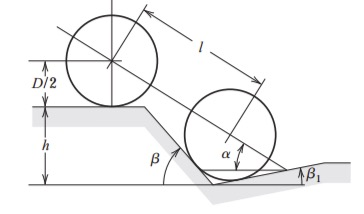

It is shown that the maximum angle $\alpha$ that can be negotiated by a vehicle when $\beta$ is the maximum angle at which hang-up failure does *not *occur satisfies the equation 


$$A\;\sin \;\alpha \;\cos \;\alpha +B\;\sin^2 \;\alpha -C\;\cos \;\alpha -E\;\sin \;\alpha =0,$$


where

$A=l\;\sin \;\beta_1$, $B=l\;\cos \;\beta_1$, $C=\left(h+0\ldotp 5D\right)\;\sin \;\beta_{1\;} -0\ldotp 5D\;\tan \;\beta_1$, and $E=\left(h+0\ldotp 5D\right)\;\cos \;\beta_1 -0\ldotp 5D$.

- It is stated that when $l=89$in., $h=49$in., $D=55$in., and $\beta_1 =11\ldotp 5\degree$, angle $\alpha$ is approximately $33\degree$. Verify this result.

- Find $\alpha \;$for the situation when $l$, $h$, and $\beta_1$ are the same as in the previous part but $D=30$in.

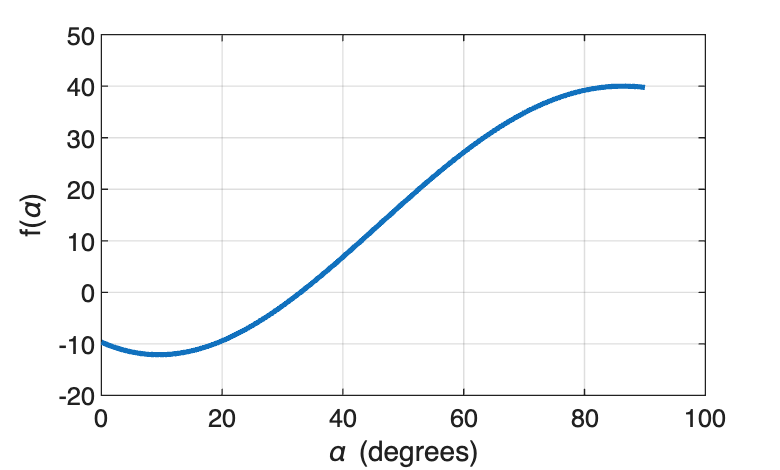

% Parameters
l=89;
h=49;
D=55;
beta=11.5*pi/180;   % convert to radians

% Coefficients
A=l*sin(beta);
B=l*cos(beta);
C=(h+0.5*D)*sin(beta)-0.5*D*tan(beta);
E=(h+0.5*D)*cos(beta)-0.5*D;

% Function
f  = @(x) A*sin(x).*cos(x) + B*(sin(x)).^2 ...
          - C*cos(x) - E*sin(x);

% Plot over 0 to 90 degrees
x = linspace(0,pi/2,1000);
plot(x*180/pi, f(x), 'LineWidth',2)
xlabel('\alpha (degrees)')
ylabel('f(\alpha)')
grid on

% ---------------------------------------------------------
% False position for solving f(x) = 0
% ---------------------------------------------------------
tolerance = 1e-8;
maxIteration = 50;
m = 31*pi/180;
n = 34*pi/180;

for k = 1:maxIteration
    c = n - f(n)*((n-m)/(f(n)-f(m)));
    if abs(f(c)) < tolerance
        fprintf('%d',c*180/pi)
    end 
    if f(c)*f(m) < 0
        n = c;
    else
        m = c;
    end
end

3.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+01

fprintf('%d',c*180/pi)

3.297217e+01

% ---------------------------------------------------------
% Bisection Method for solving f(x) = 0
% ---------------------------------------------------------
epsilon = 1e-8;
max = 1000;
m = 31*pi/180;
n = 35*pi/180;

for k=1:max
    c = (m+n)/2;
    if abs(f(c)) < epsilon || (b-a)/2 < epsilon
        fprintf('%d', c*180/pi)
    end
    if f(c)*f(m) < 0
        n = c;
    else
        m = c;
    end
end

3.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.297217e+013.29

fprintf('%d',c*180/pi)

3.297217e+01



% ---------------------------------------------------------
% Newton's Method for solving f(x) = 0
% ---------------------------------------------------------


% ---- USER INPUT ----
df = @(x) -A*(sin(x))^2+A*(cos(x))^2+2*B*sin(x)*cos(x)+C*sin(x)-E*cos(x)         % Derivative

df = function_handle with value:
    @(x)-A*(sin(x))^2+A*(cos(x))^2+2*B*sin(x)*cos(x)+C*sin(x)-E*cos(x)



x0 = 33*pi/180;                     % Initial guess
tol = 1e-8;                   % Tolerance
maxIter = 50;                 % Maximum iterations

% ---- INITIALIZATION ----
x = x0;

fprintf('Iter        x_k               f(x_k)\n');

Iter        x_k               f(x_k)


fprintf('-------------------------------------------\n');

-------------------------------------------



% ---- NEWTON ITERATION ----
for k = 1:maxIter
    
    fx  = f(x);
    dfx = df(x);
    
    % Check for zero derivative
    if abs(dfx) < eps
        error('Derivative is zero. Method fails.');
    end
    
    % Newton update
    x_new = x - fx/dfx;
    
    % Print iteration data
    fprintf('%2d   %18.12f   %12.6e\n', k, x_new, f(x_new));
    
    % Convergence check
    if abs(x_new - x) < tol
        x_new=x_new*180/pi;
        fprintf('\nConverged in %d iterations.\n', k);
        fprintf('Approximate root: %.12f\n', x_new);
        return
    end
    
    x = x_new;
    
end

 1       0.575473175590   8.546839e-06
 2       0.575473012194   9.663381e-13
 3       0.575473012194   0.000000e+00



Converged in 3 iterations.


Approximate root: 32.972174822420



fprintf('\nMaximum iterations reached.\n');
fprintf('Last approximation: %.12f\n', x);
